# Intro on machine learning classifiers (vol I). Rationale.

**Author**: Javier Ortiz-Tudela (Goethe University)

**Email**: [ortiztudela@psych.uni-frankfurt.de](mailto:ortiztudela@psych.uni-frankfurt.de)

**Created on**: 06/04/2020

**Last update on**: 12/04/2020

## Initialize some stuff.

Just run this section. Press Ctrl + Enter.

clear; close all
clc

## Intoduction

What is machine learning? Machine learning, decoding, mvpa, classification, classifier based analysis.

## Practical example (human learning)

If you see the following data sets that correspond to two conditions or classes, 1 and 2, can you see a pattern that distinguishes them?

% Condition 1 data
array1 = [51; 53; 55; 57; 59; 61; 63; 65]; 
labels1 = [1; 1; 1; 1; 1; 1; 1; 1]; % These are just the labels that code the condition of each datapoint

% Condition 2 data
array2 = [32; 34; 36; 38; 40; 42; 44; 46];
labels2 = [2; 2; 2; 2; 2; 2; 2; 2]; % These are just the labels that code the condition of each datapoint

% What is the best way of knowing whether you learn the pattern or not? Test your self:
test_observation(1)=34;

% Is test_observation a member of 1 or 2? Replace the "[]" with your answer.
your_prediction(1)=2;

% Since we know the ground truth, we can check how good your learning was. 
% Click on this section and press Ctrl. + Enter
test_label(1)=2;
if your_prediction(1) == test_label(1);accuracy(1)=1; sprintf('Yay! You did great!')
else; accuracy(1)=0;sprintf('Cueck. You did not identify the class correctly')
end

ans = 'Yay! You did great!'

## Can machines do that?

% Put all of the 'training' observations together
train_data=[array1; array2];
train_labels=[labels1;labels2];

% Train the model
classifier = fitcsvm(train_data, train_labels);

% Test its knowledge
model_prediction=predict(classifier, test_observation)

model_prediction = 2

sprintf('The model thinks the observation "%d" belongs to class %d', ...
    test_observation(1), model_prediction)

ans = 'The model thinks the observation "34" belongs to class 2'

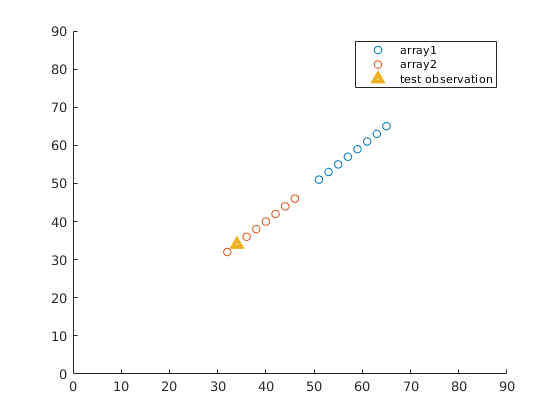


% Compute performance
acc=model_prediction==test_label;

% Display data sets 
figure; hold on
plot(array1, array1, 'o');plot(array2, array2, 'o'); 
plot(test_observation, test_observation, '^', 'LineWidth', 3);
axis([0 90 00 90]);legend({'array1'; 'array2';'test observation'})

## Validation

There is yet a better (more restrictive) way of assessing learning: Test on observations that are different from the study sets.

test_observation(2)=12;

% Is test_observation a member of 1 or 2? Replace the "[]" with your answer
your_prediction(2)=[1];

% We can ask the model that we trained before.
% Test its knowledge
model_prediction=predict(classifier, test_observation(2))

model_prediction = 2

sprintf('The model thinks the observation "%d" belongs to class %d \n and your prediction is %d.', ...
    test_observation(2), model_prediction, your_prediction(2))

ans =     'The model thinks the observation "12" belongs to class 2 
      and your prediction is 1.'


Why this disrepancy?

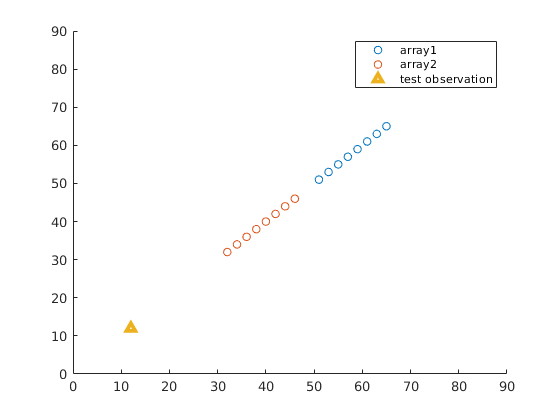

% Display data sets 
figure; hold on
plot(array1, array1, 'o');plot(array2, array2, 'o'); 
plot(test_observation(2), test_observation(2), '^', 'LineWidth', 3);
axis([0 90 00 90]);legend({'array1'; 'array2';'test observation'})

Can you guess the rule that the model has learned?

% In this case, we know the true label 
test_label(2)=2; % True label

% Assess performance
if your_prediction(2) == test_label(2);accuracy(2)=1; sprintf('Yay! You did great!')
else; accuracy(2)=0;sprintf('Cueck. You did not identify the class correctly')
end

ans = 'Cueck. You did not identify the class correctly'


% Compute performance
acc=model_prediction==test_label(2);

## Cross-validation

% We start with the same data as in the example above
data=[array1; array2];
data_labels=[labels1;labels2];

## First step: We can divide the original data set into two subsets

train_data=data(1:2:length(data)); % Odd observations
train_labels=data_labels(1:2:length(data));

test_data=data(2:2:length(data)); % Even observations
test_labels=data_labels(2:2:length(data));

% And we use the classifiers as before
% Train the model
model1 = fitcsvm(train_data, train_labels);

% Test
model_prediction=predict(classifier, test_data)

model_prediction =      1
     1
     1
     1
     2
     2
     2
     2



% Compute and store performance 
acc_fold(1)=mean(model_prediction==test_labels)

acc_fold = 1

## Second step: Now we can switch or training and test sets and repeat the procedure

train_data=data(2:2:length(data)); % Even observations
train_labels=data_labels(2:2:length(data));

test_data=data(1:2:length(data)); % Odd observations
test_labels=data_labels(1:2:length(data));

% And we use the classifiers as before
% Train the model
model2 = fitcsvm(train_data, train_labels);

% Test
model_prediction=predict(classifier, test_data)

model_prediction =      1
     1
     1
     1
     2
     2
     2
     2



% Compute and store performance 
acc_fold(2)=mean(model_prediction==test_labels);

Each one of this steps (usually refered to as "folds") outputs an accuracy measure. If we average them, we will have a measure of accuracy that has been independently validated (on each fold).

final_acc=mean(acc_fold)

final_acc = 1

## Another example of cross-validation. Leave-one-out.

Can you set a cross-validation scheme yourself?